**a)** **x =2cos(0.2*t), y = 2sen(0.4*t)**

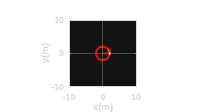

%Limpieza de pantalla
clear all
close all
clc

%1 TIEMPO %%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
tf=31.5;             % Tiempo de simulación en segundos (s)
ts=0.05;            % Tiempo de muestreo en segundos (s)
t=0:ts:tf;         % Vector de tiempo
N= length(t);      % Muestras


%2 CONDICIONES INICIALES %%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%

%Damos valores a nuestro punto inicial de posición y orientación
x1(1)=0;  %Posición inicial eje x
y1(1)=0;  %Posición inicial eje y
phi(1)=0; %Orientación inicial del robot 

%Igualamos el punto de control con las proyecciones X1 y Y1 por su
%coincidencia
hx(1)= x1(1);       % Posición del punto de control en el eje (X) metros (m)
hy(1)= y1(1);       % Posición del punto de control en el eje (Y) metros (m)

%3 TRAYECTORIA DESEADA %%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%

syms t_sym

% Ecuaciones paramétricas de la trayectoria deseada (simbólicas)
hxd_sym = 2*cos(0.2*t_sym);
hyd_sym = 2*sin(0.2*t_sym);

% Derivadas simbólicas automáticas
hxdp_sym = diff(hxd_sym, t_sym);
hydp_sym = diff(hyd_sym, t_sym);

% Convertir a funciones numéricas y evaluar sobre el vector t
hxd  = double(subs(hxd_sym,  t_sym, t));
hyd  = double(subs(hyd_sym,  t_sym, t));
hxdp = double(subs(hxdp_sym, t_sym, t));
hydp = double(subs(hydp_sym, t_sym, t));



%4 CONTROL, BUCLE DE SIMULACION %%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%

for k=1:N 

    %a)Errores de control (Aqui la posición deseada ya no es constante,
    % varia con el tiempo)
    hxe(k)=hxd(k)-hx(k);
    hye(k)=hyd(k)-hy(k);
    
    %Matriz de error
    he= [hxe(k);hye(k)];
    %Magnitud del error de posición
    Error(k)= sqrt(hxe(k)^2 +hye(k)^2);

    %b)Matriz Jacobiana
    J=[cos(phi(k)) -sin(phi(k));... %Matriz de rotación en 2D
       sin(phi(k)) cos(phi(k))];

    %c)Matriz de Ganancias
    K=[3 0;...
       0 2.5];
    
    %d)Velocidades deseadas
    hdp=[hxdp(k);hydp(k)];

    %e)Ley de Control:Agregamos las velocidades deseadas
    qpRef= pinv(J)*(hdp + K*he);

    v(k)= qpRef(1);   %Velocidad lineal de entrada al robot 
    w(k)= qpRef(2);   %Velocidad angular de entrada al robot 


%5 APLICACIÓN DE CONTROL AL ROBOT %%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%

    %Aplico la integral a la velocidad angular para obtener el angulo "phi" de la orientación
    phi(k+1)=phi(k)+w(k)*ts; % Integral numérica (método de Euler)
           
   %%%%%%%%%%%%%%%%%%%%% MODELO CINEMATICO %%%%%%%%%%%%%%%%%%%%%%%%%
    
    xp1=v(k)*cos(phi(k)); 
    yp1=v(k)*sin(phi(k));
 
    %Aplico la integral a la velocidad lineal para obtener las cordenadas
    %"x1" y "y1" de la posición
    x1(k+1)=x1(k)+ ts*xp1; % Integral numérica (método de Euler)
    y1(k+1)=y1(k)+ ts*yp1; % Integral numérica (método de Euler)

    % Posicion del robot con respecto al punto de control
    hx(k+1)=x1(k+1); 
    hy(k+1)=y1(k+1);
     

end

%%%%%%%%%%%%%%%%%%%%%%%%%%%%% SIMULACION VIRTUAL 3D %%%%%%%%%%%%%%%%%%%%%%%%%%%%

% a) Configuracion de escena

scene=figure;  % Crear figura (Escena)
set(scene,'Color','white'); % Color del fondo de la escena
set(gca,'FontWeight','bold') ;% Negrilla en los ejes y etiquetas
sizeScreen=get(0,'ScreenSize'); % Retorna el tamaño de la pantalla del computador
set(scene,'position',sizeScreen); % Configurar tamaño de la figura
camlight('headlight'); % Luz para la escena
axis equal; % Establece la relación de aspecto para que las unidades de datos sean las mismas en todas las direcciones.
grid on; % Mostrar líneas de cuadrícula en los ejes
box on; % Mostrar contorno de ejes
xlabel('x(m)'); ylabel('y(m)'); zlabel('z(m)'); % Etiqueta de los eje

view([-0.1 90]); % Orientacion de la figura
axis([-10 10 -10 10 0 1]); % Ingresar limites minimos y maximos en los ejes x y z [minX maxX minY maxY minZ maxZ]

% b) Graficar robots en la posicion inicial
scale = 4;
MobileRobot_5;
H1=MobilePlot_4(x1(1),y1(1),phi(1),scale);hold on;

% c) Graficar Trayectorias
H2=plot3(hx(1),hy(1),0,'r','lineWidth',2);
H3=plot3(hxd,hyd,zeros(1,N),'g','lineWidth',2); %Grafico circulo en posición deseada
%H4=plot3(hx(1),hy(1),0,'go','lineWidth',2);%Grafico circulo en posición inicial
% d) Bucle de simulacion de movimiento del robot

step=1; % pasos para simulacion

for k=1:step:N

    delete(H1);    
    delete(H2);
    
    H1=MobilePlot_4(x1(k),y1(k),phi(k),scale);
    H2=plot3(hx(1:k),hy(1:k),zeros(1,k),'r','lineWidth',2);
    
    pause(ts);

end

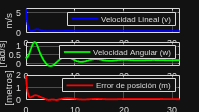


%%%%%%%%%%%%%%%%%%%%%%%%%%%%% Graficas %%%%%%%%%%%%%%%%%%%%%%%%%%%%
graph=figure;  % Crear figura (Escena)
set(graph,'position',sizeScreen); % Congigurar tamaño de la figura
subplot(311)
plot(t,v,'b','LineWidth',2),grid('on'),xlabel('Tiempo [s]'),ylabel('m/s'),legend('Velocidad Lineal (v)');
subplot(312)
plot(t,w,'g','LineWidth',2),grid('on'),xlabel('Tiempo [s]'),ylabel('[rad/s]'),legend('Velocidad Angular (w)');
subplot(313)
plot(t,Error,'r','LineWidth',2),grid('on'),xlabel('Tiempo [s]'),ylabel('[metros]'),legend('Error de posición (m)');

**b) x =t−3sen(t), y = 4−3cos(t)**

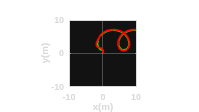

%Limpieza de pantalla
clc

%1 TIEMPO %%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
tf=31.5;             % Tiempo de simulación en segundos (s)
ts=0.05;            % Tiempo de muestreo en segundos (s)
t=0:ts:tf;         % Vector de tiempo
N= length(t);      % Muestras


%2 CONDICIONES INICIALES %%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%

%Damos valores a nuestro punto inicial de posición y orientación
x1(1)=0;  %Posición inicial eje x
y1(1)=0;  %Posición inicial eje y
phi(1)=0; %Orientación inicial del robot 

%Igualamos el punto de control con las proyecciones X1 y Y1 por su
%coincidencia
hx(1)= x1(1);       % Posición del punto de control en el eje (X) metros (m)
hy(1)= y1(1);       % Posición del punto de control en el eje (Y) metros (m)

%3 TRAYECTORIA DESEADA %%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%

syms t_sym

% Ecuaciones paramétricas de la trayectoria deseada (simbólicas)
hxd_sym = t_sym-3*sin(t_sym);
hyd_sym = 4-3*cos(t_sym);

% Derivadas simbólicas automáticas
hxdp_sym = diff(hxd_sym, t_sym);
hydp_sym = diff(hyd_sym, t_sym);

% Convertir a funciones numéricas y evaluar sobre el vector t
hxd  = double(subs(hxd_sym,  t_sym, t));
hyd  = double(subs(hyd_sym,  t_sym, t));
hxdp = double(subs(hxdp_sym, t_sym, t));
hydp = double(subs(hydp_sym, t_sym, t));



%4 CONTROL, BUCLE DE SIMULACION %%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%

for k=1:N 

    %a)Errores de control (Aqui la posición deseada ya no es constante,
    % varia con el tiempo)
    hxe(k)=hxd(k)-hx(k);
    hye(k)=hyd(k)-hy(k);
    
    %Matriz de error
    he= [hxe(k);hye(k)];
    %Magnitud del error de posición
    Error(k)= sqrt(hxe(k)^2 +hye(k)^2);

    %b)Matriz Jacobiana
    J=[cos(phi(k)) -sin(phi(k));... %Matriz de rotación en 2D
       sin(phi(k)) cos(phi(k))];

    %c)Matriz de Ganancias
    K=[8  0;...
       0  7];
    
    %d)Velocidades deseadas
    hdp=[hxdp(k);hydp(k)];

    %e)Ley de Control:Agregamos las velocidades deseadas
    qpRef= pinv(J)*(hdp + K*he);

    v(k)= qpRef(1);   %Velocidad lineal de entrada al robot 
    w(k)= qpRef(2);   %Velocidad angular de entrada al robot 


%5 APLICACIÓN DE CONTROL AL ROBOT %%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%

    %Aplico la integral a la velocidad angular para obtener el angulo "phi" de la orientación
    phi(k+1)=phi(k)+w(k)*ts; % Integral numérica (método de Euler)
           
   %%%%%%%%%%%%%%%%%%%%% MODELO CINEMATICO %%%%%%%%%%%%%%%%%%%%%%%%%
    
    xp1=v(k)*cos(phi(k)); 
    yp1=v(k)*sin(phi(k));
 
    %Aplico la integral a la velocidad lineal para obtener las cordenadas
    %"x1" y "y1" de la posición
    x1(k+1)=x1(k)+ ts*xp1; % Integral numérica (método de Euler)
    y1(k+1)=y1(k)+ ts*yp1; % Integral numérica (método de Euler)

    % Posicion del robot con respecto al punto de control
    hx(k+1)=x1(k+1); 
    hy(k+1)=y1(k+1);
     

end

%%%%%%%%%%%%%%%%%%%%%%%%%%%%% SIMULACION VIRTUAL 3D %%%%%%%%%%%%%%%%%%%%%%%%%%%%

% a) Configuracion de escena

scene=figure;  % Crear figura (Escena)
set(scene,'Color','white'); % Color del fondo de la escena
set(gca,'FontWeight','bold') ;% Negrilla en los ejes y etiquetas
sizeScreen=get(0,'ScreenSize'); % Retorna el tamaño de la pantalla del computador
set(scene,'position',sizeScreen); % Configurar tamaño de la figura
camlight('headlight'); % Luz para la escena
axis equal; % Establece la relación de aspecto para que las unidades de datos sean las mismas en todas las direcciones.
grid on; % Mostrar líneas de cuadrícula en los ejes
box on; % Mostrar contorno de ejes
xlabel('x(m)'); ylabel('y(m)'); zlabel('z(m)'); % Etiqueta de los eje

view([-0.1 90]); % Orientacion de la figura
axis([-10 10 -10 10 0 1]); % Ingresar limites minimos y maximos en los ejes x y z [minX maxX minY maxY minZ maxZ]

% b) Graficar robots en la posicion inicial
scale = 4;
MobileRobot_5;
H1=MobilePlot_4(x1(1),y1(1),phi(1),scale);hold on;

% c) Graficar Trayectorias
H2=plot3(hx(1),hy(1),0,'r','lineWidth',2);
H3=plot3(hxd,hyd,zeros(1,N),'g','lineWidth',2); %Grafico circulo en posición deseada
%H4=plot3(hx(1),hy(1),0,'go','lineWidth',2);%Grafico circulo en posición inicial
% d) Bucle de simulacion de movimiento del robot

step=1; % pasos para simulacion

for k=1:step:N

    delete(H1);    
    delete(H2);
    
    H1=MobilePlot_4(x1(k),y1(k),phi(k),scale);
    H2=plot3(hx(1:k),hy(1:k),zeros(1,k),'r','lineWidth',2);
    
    pause(ts);

end

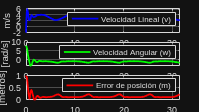


%%%%%%%%%%%%%%%%%%%%%%%%%%%%% Graficas %%%%%%%%%%%%%%%%%%%%%%%%%%%%
graph=figure;  % Crear figura (Escena)
set(graph,'position',sizeScreen); % Congigurar tamaño de la figura
subplot(311)
plot(t,v,'b','LineWidth',2),grid('on'),xlabel('Tiempo [s]'),ylabel('m/s'),legend('Velocidad Lineal (v)');
subplot(312)
plot(t,w,'g','LineWidth',2),grid('on'),xlabel('Tiempo [s]'),ylabel('[rad/s]'),legend('Velocidad Angular (w)');
subplot(313)
plot(t,Error,'r','LineWidth',2),grid('on'),xlabel('Tiempo [s]'),ylabel('[metros]'),legend('Error de posición (m)');

**c) x =3cos(t)−cos(3t), y = 4sin(3t),**

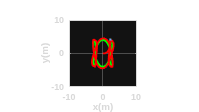

%Limpieza de pantalla
clc

%1 TIEMPO %%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
%tf=31.5;             % Tiempo de simulación en segundos (s)
tf=7;
ts=0.05;            % Tiempo de muestreo en segundos (s)
t=0:ts:tf;         % Vector de tiempo
N= length(t);      % Muestras


%2 CONDICIONES INICIALES %%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%

%Damos valores a nuestro punto inicial de posición y orientación
x1(1)=0;  %Posición inicial eje x
y1(1)=0;  %Posición inicial eje y
phi(1)=0; %Orientación inicial del robot 

%Igualamos el punto de control con las proyecciones X1 y Y1 por su
%coincidencia
hx(1)= x1(1);       % Posición del punto de control en el eje (X) metros (m)
hy(1)= y1(1);       % Posición del punto de control en el eje (Y) metros (m)

%3 TRAYECTORIA DESEADA %%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%

syms t_sym

% Ecuaciones paramétricas de la trayectoria deseada (simbólicas)
hxd_sym = 3*cos(t_sym)-cos(3*t_sym);
hyd_sym = 4*sin(3*t_sym);

% Derivadas simbólicas automáticas
hxdp_sym = diff(hxd_sym, t_sym);
hydp_sym = diff(hyd_sym, t_sym);

% Convertir a funciones numéricas y evaluar sobre el vector t
hxd  = double(subs(hxd_sym,  t_sym, t));
hyd  = double(subs(hyd_sym,  t_sym, t));
hxdp = double(subs(hxdp_sym, t_sym, t));
hydp = double(subs(hydp_sym, t_sym, t));



%4 CONTROL, BUCLE DE SIMULACION %%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%

for k=1:N 

    %a)Errores de control (Aqui la posición deseada ya no es constante,
    % varia con el tiempo)
    hxe(k)=hxd(k)-hx(k);
    hye(k)=hyd(k)-hy(k);
    
    %Matriz de error
    he= [hxe(k);hye(k)];
    %Magnitud del error de posición
    Error(k)= sqrt(hxe(k)^2 +hye(k)^2);

    %b)Matriz Jacobiana
    J=[cos(phi(k)) -sin(phi(k));... %Matriz de rotación en 2D
       sin(phi(k)) cos(phi(k))];

    %c)Matriz de Ganancias
    K=[7   0;...
       0  10];
    
    %d)Velocidades deseadas
    hdp=[hxdp(k);hydp(k)];

    %e)Ley de Control:Agregamos las velocidades deseadas
    qpRef= pinv(J)*(hdp + K*he);

    v(k)= qpRef(1);   %Velocidad lineal de entrada al robot 
    w(k)= qpRef(2);   %Velocidad angular de entrada al robot 


%5 APLICACIÓN DE CONTROL AL ROBOT %%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%

    %Aplico la integral a la velocidad angular para obtener el angulo "phi" de la orientación
    phi(k+1)=phi(k)+w(k)*ts; % Integral numérica (método de Euler)
           
   %%%%%%%%%%%%%%%%%%%%% MODELO CINEMATICO %%%%%%%%%%%%%%%%%%%%%%%%%
    
    xp1=v(k)*cos(phi(k)); 
    yp1=v(k)*sin(phi(k));
 
    %Aplico la integral a la velocidad lineal para obtener las cordenadas
    %"x1" y "y1" de la posición
    x1(k+1)=x1(k)+ ts*xp1; % Integral numérica (método de Euler)
    y1(k+1)=y1(k)+ ts*yp1; % Integral numérica (método de Euler)

    % Posicion del robot con respecto al punto de control
    hx(k+1)=x1(k+1); 
    hy(k+1)=y1(k+1);
     

end

%%%%%%%%%%%%%%%%%%%%%%%%%%%%% SIMULACION VIRTUAL 3D %%%%%%%%%%%%%%%%%%%%%%%%%%%%

% a) Configuracion de escena

scene=figure;  % Crear figura (Escena)
set(scene,'Color','white'); % Color del fondo de la escena
set(gca,'FontWeight','bold') ;% Negrilla en los ejes y etiquetas
sizeScreen=get(0,'ScreenSize'); % Retorna el tamaño de la pantalla del computador
set(scene,'position',sizeScreen); % Configurar tamaño de la figura
camlight('headlight'); % Luz para la escena
axis equal; % Establece la relación de aspecto para que las unidades de datos sean las mismas en todas las direcciones.
grid on; % Mostrar líneas de cuadrícula en los ejes
box on; % Mostrar contorno de ejes
xlabel('x(m)'); ylabel('y(m)'); zlabel('z(m)'); % Etiqueta de los eje

view([-0.1 90]); % Orientacion de la figura
axis([-10 10 -10 10 0 1]); % Ingresar limites minimos y maximos en los ejes x y z [minX maxX minY maxY minZ maxZ]

% b) Graficar robots en la posicion inicial
scale = 4;
MobileRobot_5;
H1=MobilePlot_4(x1(1),y1(1),phi(1),scale);hold on;

% c) Graficar Trayectorias
H2=plot3(hx(1),hy(1),0,'r','lineWidth',2);
H3=plot3(hxd,hyd,zeros(1,N),'g','lineWidth',2); %Grafico circulo en posición deseada
%H4=plot3(hx(1),hy(1),0,'go','lineWidth',2);%Grafico circulo en posición inicial
% d) Bucle de simulacion de movimiento del robot

step=1; % pasos para simulacion

for k=1:step:N

    delete(H1);    
    delete(H2);
    
    H1=MobilePlot_4(x1(k),y1(k),phi(k),scale);
    H2=plot3(hx(1:k),hy(1:k),zeros(1,k),'r','lineWidth',2);
    
    pause(ts);

end

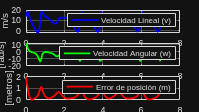

n = min([length(t), length(v), length(w), length(Error)]);
%%%%%%%%%%%%%%%%%%%%%%%%%%%%% Graficas %%%%%%%%%%%%%%%%%%%%%%%%%%%%
graph=figure;  % Crear figura (Escena)
set(graph,'position',sizeScreen); % Congigurar tamaño de la figura
subplot(311)
plot(t(1:n), v(1:n),'b','LineWidth',2),grid('on'),xlabel('Tiempo [s]'),ylabel('m/s'),legend('Velocidad Lineal (v)');
subplot(312)
plot(t(1:n), w(1:n),'g','LineWidth',2),grid('on'),xlabel('Tiempo [s]'),ylabel('[rad/s]'),legend('Velocidad Angular (w)');
subplot(313)
plot(t(1:n), Error(1:n),'r','LineWidth',2),grid('on'),xlabel('Tiempo [s]'),ylabel('[metros]'),legend('Error de posición (m)');

**d)** **x = cos(t) + 1/2cos(7t) + 1/3sen(17t), y =** **sen****(t) + 1/2sen(7t) + 1/3cos(17t)**

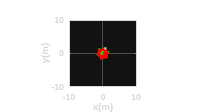

%Limpieza de pantalla
clc

%1 TIEMPO %%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
%tf=31.5;             % Tiempo de simulación en segundos (s)
tf=20;
ts=0.01;            % Tiempo de muestreo en segundos (s)
t=0:ts:tf;         % Vector de tiempo
N= length(t);      % Muestras


%2 CONDICIONES INICIALES %%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%

%Damos valores a nuestro punto inicial de posición y orientación
x1(1)=0;  %Posición inicial eje x
y1(1)=0;  %Posición inicial eje y
phi(1)=0; %Orientación inicial del robot 

%Igualamos el punto de control con las proyecciones X1 y Y1 por su
%coincidencia
hx(1)= x1(1);       % Posición del punto de control en el eje (X) metros (m)
hy(1)= y1(1);       % Posición del punto de control en el eje (Y) metros (m)

%3 TRAYECTORIA DESEADA %%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%

syms t_sym

% Ecuaciones paramétricas de la trayectoria deseada (simbólicas)
hxd_sym = cos(t_sym) + 1/2*cos(7*t_sym) + 1/3*sin(17*t_sym);
hyd_sym = sin(t_sym) + 1/2*sin(7*t_sym) + 1/3*cos(17*t_sym);

% Derivadas simbólicas automáticas
hxdp_sym = diff(hxd_sym, t_sym);
hydp_sym = diff(hyd_sym, t_sym);

% Convertir a funciones numéricas y evaluar sobre el vector t
hxd  = double(subs(hxd_sym,  t_sym, t));
hyd  = double(subs(hyd_sym,  t_sym, t));
hxdp = double(subs(hxdp_sym, t_sym, t));
hydp = double(subs(hydp_sym, t_sym, t));



%4 CONTROL, BUCLE DE SIMULACION %%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%

for k=1:N 

    %a)Errores de control (Aqui la posición deseada ya no es constante,
    % varia con el tiempo)
    hxe(k)=hxd(k)-hx(k);
    hye(k)=hyd(k)-hy(k);
    
    %Matriz de error
    he= [hxe(k);hye(k)];
    %Magnitud del error de posición
    Error(k)= sqrt(hxe(k)^2 +hye(k)^2);

    %b)Matriz Jacobiana
    J=[cos(phi(k)) -sin(phi(k));... %Matriz de rotación en 2D
       sin(phi(k)) cos(phi(k))];

    %c)Matriz de Ganancias
    K=[5  0;...
       0  6];
    
    %d)Velocidades deseadas
    hdp=[hxdp(k);hydp(k)];

    %e)Ley de Control:Agregamos las velocidades deseadas
    qpRef= pinv(J)*(hdp + K*he);

    v(k)= qpRef(1);   %Velocidad lineal de entrada al robot 
    w(k)= qpRef(2);   %Velocidad angular de entrada al robot 


%5 APLICACIÓN DE CONTROL AL ROBOT %%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%

    %Aplico la integral a la velocidad angular para obtener el angulo "phi" de la orientación
    phi(k+1)=phi(k)+w(k)*ts; % Integral numérica (método de Euler)
           
   %%%%%%%%%%%%%%%%%%%%% MODELO CINEMATICO %%%%%%%%%%%%%%%%%%%%%%%%%
    
    xp1=v(k)*cos(phi(k)); 
    yp1=v(k)*sin(phi(k));
 
    %Aplico la integral a la velocidad lineal para obtener las cordenadas
    %"x1" y "y1" de la posición
    x1(k+1)=x1(k)+ ts*xp1; % Integral numérica (método de Euler)
    y1(k+1)=y1(k)+ ts*yp1; % Integral numérica (método de Euler)

    % Posicion del robot con respecto al punto de control
    hx(k+1)=x1(k+1); 
    hy(k+1)=y1(k+1);
     

end

%%%%%%%%%%%%%%%%%%%%%%%%%%%%% SIMULACION VIRTUAL 3D %%%%%%%%%%%%%%%%%%%%%%%%%%%%

% a) Configuracion de escena

scene=figure;  % Crear figura (Escena)
set(scene,'Color','white'); % Color del fondo de la escena
set(gca,'FontWeight','bold') ;% Negrilla en los ejes y etiquetas
sizeScreen=get(0,'ScreenSize'); % Retorna el tamaño de la pantalla del computador
set(scene,'position',sizeScreen); % Configurar tamaño de la figura
camlight('headlight'); % Luz para la escena
axis equal; % Establece la relación de aspecto para que las unidades de datos sean las mismas en todas las direcciones.
grid on; % Mostrar líneas de cuadrícula en los ejes
box on; % Mostrar contorno de ejes
xlabel('x(m)'); ylabel('y(m)'); zlabel('z(m)'); % Etiqueta de los eje

view([-0.1 90]); % Orientacion de la figura
axis([-10 10 -10 10 0 1]); % Ingresar limites minimos y maximos en los ejes x y z [minX maxX minY maxY minZ maxZ]

% b) Graficar robots en la posicion inicial
scale = 4;
MobileRobot_5;
H1=MobilePlot_4(x1(1),y1(1),phi(1),scale);hold on;

% c) Graficar Trayectorias
H2=plot3(hx(1),hy(1),0,'r','lineWidth',2);
H3=plot3(hxd,hyd,zeros(1,N),'g','lineWidth',2); %Grafico circulo en posición deseada
%H4=plot3(hx(1),hy(1),0,'go','lineWidth',2);%Grafico circulo en posición inicial
% d) Bucle de simulacion de movimiento del robot

step=1; % pasos para simulacion

for k=1:step:N

    delete(H1);    
    delete(H2);
    
    H1=MobilePlot_4(x1(k),y1(k),phi(k),scale);
    H2=plot3(hx(1:k),hy(1:k),zeros(1,k),'r','lineWidth',2);
    
    pause(ts);

end

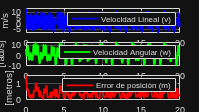

n = min([length(t), length(v), length(w), length(Error)]);
%%%%%%%%%%%%%%%%%%%%%%%%%%%%% Graficas %%%%%%%%%%%%%%%%%%%%%%%%%%%%
graph=figure;  % Crear figura (Escena)
set(graph,'position',sizeScreen); % Congigurar tamaño de la figura
subplot(311)
plot(t(1:n), v(1:n),'b','LineWidth',2),grid('on'),xlabel('Tiempo [s]'),ylabel('m/s'),legend('Velocidad Lineal (v)');
subplot(312)
plot(t(1:n), w(1:n),'g','LineWidth',2),grid('on'),xlabel('Tiempo [s]'),ylabel('[rad/s]'),legend('Velocidad Angular (w)');
subplot(313)
plot(t(1:n), Error(1:n),'r','LineWidth',2),grid('on'),xlabel('Tiempo [s]'),ylabel('[metros]'),legend('Error de posición (m)');

**e)** **x =17cos(t)+7cos(17+7t), y = 17sen(t) −7sen(17+7t),**

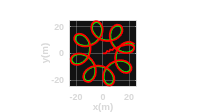

%Limpieza de pantalla
clc

%1 TIEMPO %%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
%tf=31.5;             % Tiempo de simulación en segundos (s)
tf=6.5;
ts=0.01;            % Tiempo de muestreo en segundos (s)
t=0:ts:tf;         % Vector de tiempo
N= length(t);      % Muestras

%2 CONDICIONES INICIALES %%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%

%Damos valores a nuestro punto inicial de posición y orientación
x1(1)=0;  %Posición inicial eje x
y1(1)=0;  %Posición inicial eje y
phi(1)=0; %Orientación inicial del robot 

%Igualamos el punto de control con las proyecciones X1 y Y1 por su
%coincidencia
hx(1)= x1(1);       % Posición del punto de control en el eje (X) metros (m)
hy(1)= y1(1);       % Posición del punto de control en el eje (Y) metros (m)

%3 TRAYECTORIA DESEADA %%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%

syms t_sym

% Ecuaciones paramétricas de la trayectoria deseada (simbólicas)
hxd_sym = 17*cos(t_sym) + 7*cos(17 + 7*t_sym);
hyd_sym = 17*sin(t_sym) - 7*sin(17 + 7*t_sym);

% Derivadas simbólicas automáticas
hxdp_sym = diff(hxd_sym, t_sym);
hydp_sym = diff(hyd_sym, t_sym);

% Convertir a funciones numéricas y evaluar sobre el vector t
hxd  = double(subs(hxd_sym,  t_sym, t));
hyd  = double(subs(hyd_sym,  t_sym, t));
hxdp = double(subs(hxdp_sym, t_sym, t));
hydp = double(subs(hydp_sym, t_sym, t));



%4 CONTROL, BUCLE DE SIMULACION %%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%

for k=1:N 

    %a)Errores de control (Aqui la posición deseada ya no es constante,
    % varia con el tiempo)
    hxe(k)=hxd(k)-hx(k);
    hye(k)=hyd(k)-hy(k);
    
    %Matriz de error
    he= [hxe(k);hye(k)];
    %Magnitud del error de posición
    Error(k)= sqrt(hxe(k)^2 +hye(k)^2);

    %b)Matriz Jacobiana
    J=[cos(phi(k)) -sin(phi(k));... %Matriz de rotación en 2D
       sin(phi(k)) cos(phi(k))];

    %c)Matriz de Ganancias
    K=[12  0;...
       0  12];
    
    %d)Velocidades deseadas
    hdp=[hxdp(k);hydp(k)];

    %e)Ley de Control:Agregamos las velocidades deseadas
    qpRef= pinv(J)*(hdp + K*he);

    v(k)= qpRef(1);   %Velocidad lineal de entrada al robot 
    w(k)= qpRef(2);   %Velocidad angular de entrada al robot 


%5 APLICACIÓN DE CONTROL AL ROBOT %%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%

    %Aplico la integral a la velocidad angular para obtener el angulo "phi" de la orientación
    phi(k+1)=phi(k)+w(k)*ts; % Integral numérica (método de Euler)
           
   %%%%%%%%%%%%%%%%%%%%% MODELO CINEMATICO %%%%%%%%%%%%%%%%%%%%%%%%%
    
    xp1=v(k)*cos(phi(k)); 
    yp1=v(k)*sin(phi(k));
 
    %Aplico la integral a la velocidad lineal para obtener las cordenadas
    %"x1" y "y1" de la posición
    x1(k+1)=x1(k)+ ts*xp1; % Integral numérica (método de Euler)
    y1(k+1)=y1(k)+ ts*yp1; % Integral numérica (método de Euler)

    % Posicion del robot con respecto al punto de control
    hx(k+1)=x1(k+1); 
    hy(k+1)=y1(k+1);
     

end

%%%%%%%%%%%%%%%%%%%%%%%%%%%%% SIMULACION VIRTUAL 3D %%%%%%%%%%%%%%%%%%%%%%%%%%%%

% a) Configuracion de escena

scene=figure;  % Crear figura (Escena)
set(scene,'Color','white'); % Color del fondo de la escena
set(gca,'FontWeight','bold') ;% Negrilla en los ejes y etiquetas
sizeScreen=get(0,'ScreenSize'); % Retorna el tamaño de la pantalla del computador
set(scene,'position',sizeScreen); % Configurar tamaño de la figura
camlight('headlight'); % Luz para la escena
axis equal; % Establece la relación de aspecto para que las unidades de datos sean las mismas en todas las direcciones.
grid on; % Mostrar líneas de cuadrícula en los ejes
box on; % Mostrar contorno de ejes
xlabel('x(m)'); ylabel('y(m)'); zlabel('z(m)'); % Etiqueta de los eje

view([-0.1 90]); % Orientacion de la figura
axis([-25 25 -25 25 0 1]); % Ingresar limites minimos y maximos en los ejes x y z [minX maxX minY maxY minZ maxZ]

% b) Graficar robots en la posicion inicial
scale = 4;
MobileRobot_5;
H1=MobilePlot_4(x1(1),y1(1),phi(1),scale);hold on;

% c) Graficar Trayectorias
H2=plot3(hx(1),hy(1),0,'r','lineWidth',2);
H3=plot3(hxd,hyd,zeros(1,N),'g','lineWidth',2); %Grafico circulo en posición deseada
%H4=plot3(hx(1),hy(1),0,'go','lineWidth',2);%Grafico circulo en posición inicial
% d) Bucle de simulacion de movimiento del robot

step=1; % pasos para simulacion

for k=1:step:N

    delete(H1);    
    delete(H2);
    
    H1=MobilePlot_4(x1(k),y1(k),phi(k),scale);
    H2=plot3(hx(1:k),hy(1:k),zeros(1,k),'r','lineWidth',2);
    
    pause(ts);

end

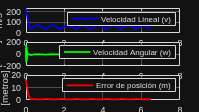

n = min([length(t), length(v), length(w), length(Error)]);
%%%%%%%%%%%%%%%%%%%%%%%%%%%%% Graficas %%%%%%%%%%%%%%%%%%%%%%%%%%%%
graph=figure;  % Crear figura (Escena)
set(graph,'position',sizeScreen); % Congigurar tamaño de la figura
subplot(311)
plot(t(1:n), v(1:n),'b','LineWidth',2),grid('on'),xlabel('Tiempo [s]'),ylabel('m/s'),legend('Velocidad Lineal (v)');
subplot(312)
plot(t(1:n), w(1:n),'g','LineWidth',2),grid('on'),xlabel('Tiempo [s]'),ylabel('[rad/s]'),legend('Velocidad Angular (w)');
subplot(313)
plot(t(1:n), Error(1:n),'r','LineWidth',2),grid('on'),xlabel('Tiempo [s]'),ylabel('[metros]'),legend('Error de posición (m)');

**f)** **x =2cos(t), y = 2sen(t)**

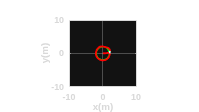

%Limpieza de pantalla
clc

%1 TIEMPO %%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
%tf=31.5;             % Tiempo de simulación en segundos (s)
tf=6.5;
ts=0.01;            % Tiempo de muestreo en segundos (s)
t=0:ts:tf;         % Vector de tiempo
N= length(t);      % Muestras

%2 CONDICIONES INICIALES %%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%

%Damos valores a nuestro punto inicial de posición y orientación
x1(1)=0;  %Posición inicial eje x
y1(1)=0;  %Posición inicial eje y
phi(1)=0; %Orientación inicial del robot 

%Igualamos el punto de control con las proyecciones X1 y Y1 por su
%coincidencia
hx(1)= x1(1);       % Posición del punto de control en el eje (X) metros (m)
hy(1)= y1(1);       % Posición del punto de control en el eje (Y) metros (m)

%3 TRAYECTORIA DESEADA %%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%

syms t_sym

% Ecuaciones paramétricas de la trayectoria deseada (simbólicas)
hxd_sym = 2*cos(t_sym);
hyd_sym = 2*sin(t_sym);

% Derivadas simbólicas automáticas
hxdp_sym = diff(hxd_sym, t_sym);
hydp_sym = diff(hyd_sym, t_sym);

% Convertir a funciones numéricas y evaluar sobre el vector t
hxd  = double(subs(hxd_sym,  t_sym, t));
hyd  = double(subs(hyd_sym,  t_sym, t));
hxdp = double(subs(hxdp_sym, t_sym, t));
hydp = double(subs(hydp_sym, t_sym, t));



%4 CONTROL, BUCLE DE SIMULACION %%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%

for k=1:N 

    %a)Errores de control (Aqui la posición deseada ya no es constante,
    % varia con el tiempo)
    hxe(k)=hxd(k)-hx(k);
    hye(k)=hyd(k)-hy(k);
    
    %Matriz de error
    he= [hxe(k);hye(k)];
    %Magnitud del error de posición
    Error(k)= sqrt(hxe(k)^2 +hye(k)^2);

    %b)Matriz Jacobiana
    J=[cos(phi(k)) -sin(phi(k));... %Matriz de rotación en 2D
       sin(phi(k)) cos(phi(k))];

    %c)Matriz de Ganancias
    K=[10  0;...
       0  9.5];
    
    %d)Velocidades deseadas
    hdp=[hxdp(k);hydp(k)];

    %e)Ley de Control:Agregamos las velocidades deseadas
    qpRef= pinv(J)*(hdp + K*he);

    v(k)= qpRef(1);   %Velocidad lineal de entrada al robot 
    w(k)= qpRef(2);   %Velocidad angular de entrada al robot 


%5 APLICACIÓN DE CONTROL AL ROBOT %%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%

    %Aplico la integral a la velocidad angular para obtener el angulo "phi" de la orientación
    phi(k+1)=phi(k)+w(k)*ts; % Integral numérica (método de Euler)
           
   %%%%%%%%%%%%%%%%%%%%% MODELO CINEMATICO %%%%%%%%%%%%%%%%%%%%%%%%%
    
    xp1=v(k)*cos(phi(k)); 
    yp1=v(k)*sin(phi(k));
 
    %Aplico la integral a la velocidad lineal para obtener las cordenadas
    %"x1" y "y1" de la posición
    x1(k+1)=x1(k)+ ts*xp1; % Integral numérica (método de Euler)
    y1(k+1)=y1(k)+ ts*yp1; % Integral numérica (método de Euler)

    % Posicion del robot con respecto al punto de control
    hx(k+1)=x1(k+1); 
    hy(k+1)=y1(k+1);
     

end

%%%%%%%%%%%%%%%%%%%%%%%%%%%%% SIMULACION VIRTUAL 3D %%%%%%%%%%%%%%%%%%%%%%%%%%%%

% a) Configuracion de escena

scene=figure;  % Crear figura (Escena)
set(scene,'Color','white'); % Color del fondo de la escena
set(gca,'FontWeight','bold') ;% Negrilla en los ejes y etiquetas
sizeScreen=get(0,'ScreenSize'); % Retorna el tamaño de la pantalla del computador
set(scene,'position',sizeScreen); % Configurar tamaño de la figura
camlight('headlight'); % Luz para la escena
axis equal; % Establece la relación de aspecto para que las unidades de datos sean las mismas en todas las direcciones.
grid on; % Mostrar líneas de cuadrícula en los ejes
box on; % Mostrar contorno de ejes
xlabel('x(m)'); ylabel('y(m)'); zlabel('z(m)'); % Etiqueta de los eje

view([-0.1 90]); % Orientacion de la figura
axis([-10 10 -10 10 0 1]); % Ingresar limites minimos y maximos en los ejes x y z [minX maxX minY maxY minZ maxZ]

% b) Graficar robots en la posicion inicial
scale = 4;
MobileRobot_5;
H1=MobilePlot_4(x1(1),y1(1),phi(1),scale);hold on;

% c) Graficar Trayectorias
H2=plot3(hx(1),hy(1),0,'r','lineWidth',2);
H3=plot3(hxd,hyd,zeros(1,N),'g','lineWidth',2); %Grafico circulo en posición deseada
%H4=plot3(hx(1),hy(1),0,'go','lineWidth',2);%Grafico circulo en posición inicial
% d) Bucle de simulacion de movimiento del robot

step=1; % pasos para simulacion

for k=1:step:N

    delete(H1);    
    delete(H2);
    
    H1=MobilePlot_4(x1(k),y1(k),phi(k),scale);
    H2=plot3(hx(1:k),hy(1:k),zeros(1,k),'r','lineWidth',2);
    
    pause(ts);

end

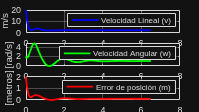

n = min([length(t), length(v), length(w), length(Error)]);
%%%%%%%%%%%%%%%%%%%%%%%%%%%%% Graficas %%%%%%%%%%%%%%%%%%%%%%%%%%%%
graph=figure;  % Crear figura (Escena)
set(graph,'position',sizeScreen); % Congigurar tamaño de la figura
subplot(311)
plot(t(1:n), v(1:n),'b','LineWidth',2),grid('on'),xlabel('Tiempo [s]'),ylabel('m/s'),legend('Velocidad Lineal (v)');
subplot(312)
plot(t(1:n), w(1:n),'g','LineWidth',2),grid('on'),xlabel('Tiempo [s]'),ylabel('[rad/s]'),legend('Velocidad Angular (w)');
subplot(313)
plot(t(1:n), Error(1:n),'r','LineWidth',2),grid('on'),xlabel('Tiempo [s]'),ylabel('[metros]'),legend('Error de posición (m)');

**g)** **x =5t−4sen(t), y = 5t−4cos(t)**

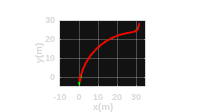

%Limpieza de pantalla
clc

%1 TIEMPO %%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
%tf=31.5;             % Tiempo de simulación en segundos (s)
tf=6.5;
ts=0.01;            % Tiempo de muestreo en segundos (s)
t=0:ts:tf;         % Vector de tiempo
N= length(t);      % Muestras

%2 CONDICIONES INICIALES %%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%

%Damos valores a nuestro punto inicial de posición y orientación
x1(1)=0;  %Posición inicial eje x
y1(1)=0;  %Posición inicial eje y
phi(1)=0; %Orientación inicial del robot 

%Igualamos el punto de control con las proyecciones X1 y Y1 por su
%coincidencia
hx(1)= x1(1);       % Posición del punto de control en el eje (X) metros (m)
hy(1)= y1(1);       % Posición del punto de control en el eje (Y) metros (m)

%3 TRAYECTORIA DESEADA %%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%

syms t_sym

% Ecuaciones paramétricas de la trayectoria deseada (simbólicas)
hxd_sym = 5*t_sym - 4*sin(t_sym);
hyd_sym = 5*t_sym - 4*cos(t_sym);

% Derivadas simbólicas automáticas
hxdp_sym = diff(hxd_sym, t_sym);
hydp_sym = diff(hyd_sym, t_sym);

% Convertir a funciones numéricas y evaluar sobre el vector t
hxd  = double(subs(hxd_sym,  t_sym, t));
hyd  = double(subs(hyd_sym,  t_sym, t));
hxdp = double(subs(hxdp_sym, t_sym, t));
hydp = double(subs(hydp_sym, t_sym, t));



%4 CONTROL, BUCLE DE SIMULACION %%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%

for k=1:N 

    %a)Errores de control (Aqui la posición deseada ya no es constante,
    % varia con el tiempo)
    hxe(k)=hxd(k)-hx(k);
    hye(k)=hyd(k)-hy(k);
    
    %Matriz de error
    he= [hxe(k);hye(k)];
    %Magnitud del error de posición
    Error(k)= sqrt(hxe(k)^2 +hye(k)^2);

    %b)Matriz Jacobiana
    J=[cos(phi(k)) -sin(phi(k));... %Matriz de rotación en 2D
       sin(phi(k)) cos(phi(k))];

    %c)Matriz de Ganancias
    K=[9  0;...
       0  11];
    
    %d)Velocidades deseadas
    hdp=[hxdp(k);hydp(k)];

    %e)Ley de Control:Agregamos las velocidades deseadas
    qpRef= pinv(J)*(hdp + K*he);

    v(k)= qpRef(1);   %Velocidad lineal de entrada al robot 
    w(k)= qpRef(2);   %Velocidad angular de entrada al robot 


%5 APLICACIÓN DE CONTROL AL ROBOT %%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%

    %Aplico la integral a la velocidad angular para obtener el angulo "phi" de la orientación
    phi(k+1)=phi(k)+w(k)*ts; % Integral numérica (método de Euler)
           
   %%%%%%%%%%%%%%%%%%%%% MODELO CINEMATICO %%%%%%%%%%%%%%%%%%%%%%%%%
    
    xp1=v(k)*cos(phi(k)); 
    yp1=v(k)*sin(phi(k));
 
    %Aplico la integral a la velocidad lineal para obtener las cordenadas
    %"x1" y "y1" de la posición
    x1(k+1)=x1(k)+ ts*xp1; % Integral numérica (método de Euler)
    y1(k+1)=y1(k)+ ts*yp1; % Integral numérica (método de Euler)

    % Posicion del robot con respecto al punto de control
    hx(k+1)=x1(k+1); 
    hy(k+1)=y1(k+1);
     

end

%%%%%%%%%%%%%%%%%%%%%%%%%%%%% SIMULACION VIRTUAL 3D %%%%%%%%%%%%%%%%%%%%%%%%%%%%

% a) Configuracion de escena

scene=figure;  % Crear figura (Escena)
set(scene,'Color','white'); % Color del fondo de la escena
set(gca,'FontWeight','bold') ;% Negrilla en los ejes y etiquetas
sizeScreen=get(0,'ScreenSize'); % Retorna el tamaño de la pantalla del computador
set(scene,'position',sizeScreen); % Configurar tamaño de la figura
camlight('headlight'); % Luz para la escena
axis equal; % Establece la relación de aspecto para que las unidades de datos sean las mismas en todas las direcciones.
grid on; % Mostrar líneas de cuadrícula en los ejes
box on; % Mostrar contorno de ejes
xlabel('x(m)'); ylabel('y(m)'); zlabel('z(m)'); % Etiqueta de los eje

view([-0.1 90]); % Orientacion de la figura
axis([-10 35 -5 30 0 1]); % Ingresar limites minimos y maximos en los ejes x y z [minX maxX minY maxY minZ maxZ]

% b) Graficar robots en la posicion inicial
scale = 4;
MobileRobot_5;
H1=MobilePlot_4(x1(1),y1(1),phi(1),scale);hold on;

% c) Graficar Trayectorias
H2=plot3(hx(1),hy(1),0,'r','lineWidth',2);
H3=plot3(hxd,hyd,zeros(1,N),'g','lineWidth',2); %Grafico circulo en posición deseada
%H4=plot3(hx(1),hy(1),0,'go','lineWidth',2);%Grafico circulo en posición inicial
% d) Bucle de simulacion de movimiento del robot

step=1; % pasos para simulacion

for k=1:step:N

    delete(H1);    
    delete(H2);
    
    H1=MobilePlot_4(x1(k),y1(k),phi(k),scale);
    H2=plot3(hx(1:k),hy(1:k),zeros(1,k),'r','lineWidth',2);
    
    pause(ts);

end

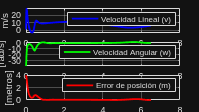

n = min([length(t), length(v), length(w), length(Error)]);
%%%%%%%%%%%%%%%%%%%%%%%%%%%%% Graficas %%%%%%%%%%%%%%%%%%%%%%%%%%%%
graph=figure;  % Crear figura (Escena)
set(graph,'position',sizeScreen); % Congigurar tamaño de la figura
subplot(311)
plot(t(1:n), v(1:n),'b','LineWidth',2),grid('on'),xlabel('Tiempo [s]'),ylabel('m/s'),legend('Velocidad Lineal (v)');
subplot(312)
plot(t(1:n), w(1:n),'g','LineWidth',2),grid('on'),xlabel('Tiempo [s]'),ylabel('[rad/s]'),legend('Velocidad Angular (w)');
subplot(313)
plot(t(1:n), Error(1:n),'r','LineWidth',2),grid('on'),xlabel('Tiempo [s]'),ylabel('[metros]'),legend('Error de posición (m)');

**h)** **x =4cos(t)+cos(4t), y = 4sen(t) −****sen****(4t)**

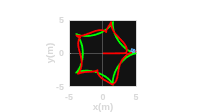

%Limpieza de pantalla
clc

%1 TIEMPO %%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
%tf=31.5;             % Tiempo de simulación en segundos (s)
tf=6.5;
ts=0.01;            % Tiempo de muestreo en segundos (s)
t=0:ts:tf;         % Vector de tiempo
N= length(t);      % Muestras

%2 CONDICIONES INICIALES %%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%

%Damos valores a nuestro punto inicial de posición y orientación
x1(1)=0;  %Posición inicial eje x
y1(1)=0;  %Posición inicial eje y
phi(1)=0; %Orientación inicial del robot 

%Igualamos el punto de control con las proyecciones X1 y Y1 por su
%coincidencia
hx(1)= x1(1);       % Posición del punto de control en el eje (X) metros (m)
hy(1)= y1(1);       % Posición del punto de control en el eje (Y) metros (m)

%3 TRAYECTORIA DESEADA %%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%

syms t_sym

% Ecuaciones paramétricas de la trayectoria deseada (simbólicas)
hxd_sym = 4*cos(t_sym) + cos(4*t_sym);
hyd_sym = 4*sin(t_sym) - sin(4*t_sym);

% Derivadas simbólicas automáticas
hxdp_sym = diff(hxd_sym, t_sym);
hydp_sym = diff(hyd_sym, t_sym);

% Convertir a funciones numéricas y evaluar sobre el vector t
hxd  = double(subs(hxd_sym,  t_sym, t));
hyd  = double(subs(hyd_sym,  t_sym, t));
hxdp = double(subs(hxdp_sym, t_sym, t));
hydp = double(subs(hydp_sym, t_sym, t));



%4 CONTROL, BUCLE DE SIMULACION %%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%

for k=1:N 

    %a)Errores de control (Aqui la posición deseada ya no es constante,
    % varia con el tiempo)
    hxe(k)=hxd(k)-hx(k);
    hye(k)=hyd(k)-hy(k);
    
    %Matriz de error
    he= [hxe(k);hye(k)];
    %Magnitud del error de posición
    Error(k)= sqrt(hxe(k)^2 +hye(k)^2);

    %b)Matriz Jacobiana
    J=[cos(phi(k)) -sin(phi(k));... %Matriz de rotación en 2D
       sin(phi(k)) cos(phi(k))];

    %c)Matriz de Ganancias
    K=[6  0;...
       0  6];
    
    %d)Velocidades deseadas
    hdp=[hxdp(k);hydp(k)];

    %e)Ley de Control:Agregamos las velocidades deseadas
    qpRef= pinv(J)*(hdp + K*he);

    v(k)= qpRef(1);   %Velocidad lineal de entrada al robot 
    w(k)= qpRef(2);   %Velocidad angular de entrada al robot 


%5 APLICACIÓN DE CONTROL AL ROBOT %%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%

    %Aplico la integral a la velocidad angular para obtener el angulo "phi" de la orientación
    phi(k+1)=phi(k)+w(k)*ts; % Integral numérica (método de Euler)
           
   %%%%%%%%%%%%%%%%%%%%% MODELO CINEMATICO %%%%%%%%%%%%%%%%%%%%%%%%%
    
    xp1=v(k)*cos(phi(k)); 
    yp1=v(k)*sin(phi(k));
 
    %Aplico la integral a la velocidad lineal para obtener las cordenadas
    %"x1" y "y1" de la posición
    x1(k+1)=x1(k)+ ts*xp1; % Integral numérica (método de Euler)
    y1(k+1)=y1(k)+ ts*yp1; % Integral numérica (método de Euler)

    % Posicion del robot con respecto al punto de control
    hx(k+1)=x1(k+1); 
    hy(k+1)=y1(k+1);
     

end

%%%%%%%%%%%%%%%%%%%%%%%%%%%%% SIMULACION VIRTUAL 3D %%%%%%%%%%%%%%%%%%%%%%%%%%%%

% a) Configuracion de escena

scene=figure;  % Crear figura (Escena)
set(scene,'Color','white'); % Color del fondo de la escena
set(gca,'FontWeight','bold') ;% Negrilla en los ejes y etiquetas
sizeScreen=get(0,'ScreenSize'); % Retorna el tamaño de la pantalla del computador
set(scene,'position',sizeScreen); % Configurar tamaño de la figura
camlight('headlight'); % Luz para la escena
axis equal; % Establece la relación de aspecto para que las unidades de datos sean las mismas en todas las direcciones.
grid on; % Mostrar líneas de cuadrícula en los ejes
box on; % Mostrar contorno de ejes
xlabel('x(m)'); ylabel('y(m)'); zlabel('z(m)'); % Etiqueta de los eje

view([-0.1 90]); % Orientacion de la figura
axis([-5 5 -5 5 0 1]); % Ingresar limites minimos y maximos en los ejes x y z [minX maxX minY maxY minZ maxZ]

% b) Graficar robots en la posicion inicial
scale = 4;
MobileRobot_5;
H1=MobilePlot_4(x1(1),y1(1),phi(1),scale);hold on;

% c) Graficar Trayectorias
H2=plot3(hx(1),hy(1),0,'r','lineWidth',2);
H3=plot3(hxd,hyd,zeros(1,N),'g','lineWidth',2); %Grafico circulo en posición deseada
%H4=plot3(hx(1),hy(1),0,'go','lineWidth',2);%Grafico circulo en posición inicial
% d) Bucle de simulacion de movimiento del robot

step=1; % pasos para simulacion

for k=1:step:N

    delete(H1);    
    delete(H2);
    
    H1=MobilePlot_4(x1(k),y1(k),phi(k),scale);
    H2=plot3(hx(1:k),hy(1:k),zeros(1,k),'r','lineWidth',2);
    
    pause(ts);

end

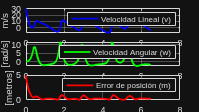

n = min([length(t), length(v), length(w), length(Error)]);
%%%%%%%%%%%%%%%%%%%%%%%%%%%%% Graficas %%%%%%%%%%%%%%%%%%%%%%%%%%%%
graph=figure;  % Crear figura (Escena)
set(graph,'position',sizeScreen); % Congigurar tamaño de la figura
subplot(311)
plot(t(1:n), v(1:n),'b','LineWidth',2),grid('on'),xlabel('Tiempo [s]'),ylabel('m/s'),legend('Velocidad Lineal (v)');
subplot(312)
plot(t(1:n), w(1:n),'g','LineWidth',2),grid('on'),xlabel('Tiempo [s]'),ylabel('[rad/s]'),legend('Velocidad Angular (w)');
subplot(313)
plot(t(1:n), Error(1:n),'r','LineWidth',2),grid('on'),xlabel('Tiempo [s]'),ylabel('[metros]'),legend('Error de posición (m)');

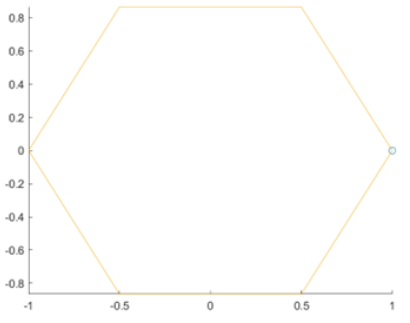

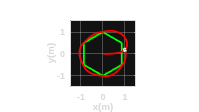

%Limpieza de pantalla
clc

%1 TIEMPO %%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
%tf=31.5;             % Tiempo de simulación en segundos (s)
tf=6.5;
ts=0.01;            % Tiempo de muestreo en segundos (s)
t=0:ts:tf;         % Vector de tiempo
N= length(t);      % Muestras

%2 CONDICIONES INICIALES %%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%

%Damos valores a nuestro punto inicial de posición y orientación
x1(1)=0;  %Posición inicial eje x
y1(1)=0;  %Posición inicial eje y
phi(1)=0; %Orientación inicial del robot 

%Igualamos el punto de control con las proyecciones X1 y Y1 por su
%coincidencia
hx(1)= x1(1);       % Posición del punto de control en el eje (X) metros (m)
hy(1)= y1(1);       % Posición del punto de control en el eje (Y) metros (m)

%3 TRAYECTORIA DESEADA %%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%

% Ángulo normalizado al sector [-π/6, π/6] de cada lado
theta = mod(t + pi/6, pi/3) - pi/6;

% Radio variable que produce los lados rectos
r_t = cos(pi/6) ./ cos(theta);

% Trayectoria
hxd = r_t .* cos(t);
hyd = r_t .* sin(t);

% Derivadas numéricas con diferencias centradas (gradient)
hxdp = gradient(hxd, ts);
hydp = gradient(hyd, ts);



%4 CONTROL, BUCLE DE SIMULACION %%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%

for k=1:N 

    %a)Errores de control (Aqui la posición deseada ya no es constante,
    % varia con el tiempo)
    hxe(k)=hxd(k)-hx(k);
    hye(k)=hyd(k)-hy(k);
    
    %Matriz de error
    he= [hxe(k);hye(k)];
    %Magnitud del error de posición
    Error(k)= sqrt(hxe(k)^2 +hye(k)^2);

    %b)Matriz Jacobiana
    J=[cos(phi(k)) -sin(phi(k));... %Matriz de rotación en 2D
       sin(phi(k)) cos(phi(k))];

    %c)Matriz de Ganancias
    K=[8  0;...
       0  8];
    
    %d)Velocidades deseadas
    hdp=[hxdp(k);hydp(k)];

    %e)Ley de Control:Agregamos las velocidades deseadas
    qpRef= pinv(J)*(hdp + K*he);

    v(k)= qpRef(1);   %Velocidad lineal de entrada al robot 
    w(k)= qpRef(2);   %Velocidad angular de entrada al robot 


%5 APLICACIÓN DE CONTROL AL ROBOT %%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%

    %Aplico la integral a la velocidad angular para obtener el angulo "phi" de la orientación
    phi(k+1)=phi(k)+w(k)*ts; % Integral numérica (método de Euler)
           
   %%%%%%%%%%%%%%%%%%%%% MODELO CINEMATICO %%%%%%%%%%%%%%%%%%%%%%%%%
    
    xp1=v(k)*cos(phi(k)); 
    yp1=v(k)*sin(phi(k));
 
    %Aplico la integral a la velocidad lineal para obtener las cordenadas
    %"x1" y "y1" de la posición
    x1(k+1)=x1(k)+ ts*xp1; % Integral numérica (método de Euler)
    y1(k+1)=y1(k)+ ts*yp1; % Integral numérica (método de Euler)

    % Posicion del robot con respecto al punto de control
    hx(k+1)=x1(k+1); 
    hy(k+1)=y1(k+1);
     

end

%%%%%%%%%%%%%%%%%%%%%%%%%%%%% SIMULACION VIRTUAL 3D %%%%%%%%%%%%%%%%%%%%%%%%%%%%

% a) Configuracion de escena

scene=figure;  % Crear figura (Escena)
set(scene,'Color','white'); % Color del fondo de la escena
set(gca,'FontWeight','bold') ;% Negrilla en los ejes y etiquetas
sizeScreen=get(0,'ScreenSize'); % Retorna el tamaño de la pantalla del computador
set(scene,'position',sizeScreen); % Configurar tamaño de la figura
camlight('headlight'); % Luz para la escena
axis equal; % Establece la relación de aspecto para que las unidades de datos sean las mismas en todas las direcciones.
grid on; % Mostrar líneas de cuadrícula en los ejes
box on; % Mostrar contorno de ejes
xlabel('x(m)'); ylabel('y(m)'); zlabel('z(m)'); % Etiqueta de los eje

view([-0.1 90]); % Orientacion de la figura
axis([-1.5 1.5 -1.5 1.55 0 1]); % Ingresar limites minimos y maximos en los ejes x y z [minX maxX minY maxY minZ maxZ]

% b) Graficar robots en la posicion inicial
scale = 1;
MobileRobot_5;
H1=MobilePlot_4(x1(1),y1(1),phi(1),scale);hold on;

% c) Graficar Trayectorias
H2=plot3(hx(1),hy(1),0,'r','lineWidth',2);
H3=plot3(hxd,hyd,zeros(1,N),'g','lineWidth',2); %Grafico circulo en posición deseada
%H4=plot3(hx(1),hy(1),0,'go','lineWidth',2);%Grafico circulo en posición inicial
% d) Bucle de simulacion de movimiento del robot

step=1; % pasos para simulacion

for k=1:step:N

    delete(H1);    
    delete(H2);
    
    H1=MobilePlot_4(x1(k),y1(k),phi(k),scale);
    H2=plot3(hx(1:k),hy(1:k),zeros(1,k),'r','lineWidth',2);
    
    pause(ts);

end

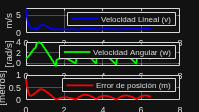


n = min([length(t), length(v), length(w), length(Error)]);
%%%%%%%%%%%%%%%%%%%%%%%%%%%%% Graficas %%%%%%%%%%%%%%%%%%%%%%%%%%%%
graph=figure;  % Crear figura (Escena)
set(graph,'position',sizeScreen); % Congigurar tamaño de la figura
subplot(311)
plot(t(1:n), v(1:n),'b','LineWidth',2),grid('on'),xlabel('Tiempo [s]'),ylabel('m/s'),legend('Velocidad Lineal (v)');
subplot(312)
plot(t(1:n), w(1:n),'g','LineWidth',2),grid('on'),xlabel('Tiempo [s]'),ylabel('[rad/s]'),legend('Velocidad Angular (w)');
subplot(313)
plot(t(1:n), Error(1:n),'r','LineWidth',2),grid('on'),xlabel('Tiempo [s]'),ylabel('[metros]'),legend('Error de posición (m)');

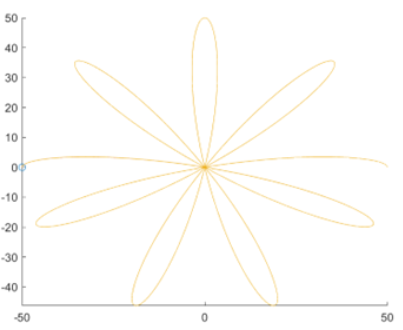

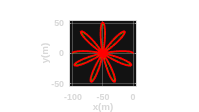

%Limpieza de pantalla
clear all
close all
clc

%1 TIEMPO %%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
%tf=31.5;             % Tiempo de simulación en segundos (s)
tf=6.5;
ts=0.01;            % Tiempo de muestreo en segundos (s)
t=0:ts:tf;         % Vector de tiempo
N= length(t);      % Muestras

%2 CONDICIONES INICIALES %%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%

%Damos valores a nuestro punto inicial de posición y orientación
x1(1)=0;  %Posición inicial eje x
y1(1)=0;  %Posición inicial eje y
phi(1)=0; %Orientación inicial del robot 

%Igualamos el punto de control con las proyecciones X1 y Y1 por su
%coincidencia
hx(1)= x1(1);       % Posición del punto de control en el eje (X) metros (m)
hy(1)= y1(1);       % Posición del punto de control en el eje (Y) metros (m)

%3 TRAYECTORIA DESEADA %%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%

t2   = (t - t(1)) / (t(end) - t(1)) * pi;
hxd  = 50 .* cos(8 .* t2) .* cos(t2);
hyd  = 50 .* cos(8 .* t2) .* sin(t2);

% Desplazar para que empiece en (0,0)
hxd  = hxd - hxd(1);
hyd  = hyd - hyd(1);

hxdp = gradient(hxd, ts);
hydp = gradient(hyd, ts);


%4 CONTROL, BUCLE DE SIMULACION %%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%

for k=1:N 

    %a)Errores de control (Aqui la posición deseada ya no es constante,
    % varia con el tiempo)
    hxe(k)=hxd(k)-hx(k);
    hye(k)=hyd(k)-hy(k);
    
    %Matriz de error
    he= [hxe(k);hye(k)];
    %Magnitud del error de posición
    Error(k)= sqrt(hxe(k)^2 +hye(k)^2);

    %b)Matriz Jacobiana
    J=[cos(phi(k)) -sin(phi(k));... %Matriz de rotación en 2D
       sin(phi(k)) cos(phi(k))];

    %c)Matriz de Ganancias
    K=[8  0;...
       0  8];
    
    %d)Velocidades deseadas
    hdp=[hxdp(k);hydp(k)];

    %e)Ley de Control:Agregamos las velocidades deseadas
    qpRef= pinv(J)*(hdp + K*he);

    v(k)= qpRef(1);   %Velocidad lineal de entrada al robot 
    w(k)= qpRef(2);   %Velocidad angular de entrada al robot 


%5 APLICACIÓN DE CONTROL AL ROBOT %%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%

    %Aplico la integral a la velocidad angular para obtener el angulo "phi" de la orientación
    phi(k+1)=phi(k)+w(k)*ts; % Integral numérica (método de Euler)
           
   %%%%%%%%%%%%%%%%%%%%% MODELO CINEMATICO %%%%%%%%%%%%%%%%%%%%%%%%%
    
    xp1=v(k)*cos(phi(k)); 
    yp1=v(k)*sin(phi(k));
 
    %Aplico la integral a la velocidad lineal para obtener las cordenadas
    %"x1" y "y1" de la posición
    x1(k+1)=x1(k)+ ts*xp1; % Integral numérica (método de Euler)
    y1(k+1)=y1(k)+ ts*yp1; % Integral numérica (método de Euler)

    % Posicion del robot con respecto al punto de control
    hx(k+1)=x1(k+1); 
    hy(k+1)=y1(k+1);
     

end

%%%%%%%%%%%%%%%%%%%%%%%%%%%%% SIMULACION VIRTUAL 3D %%%%%%%%%%%%%%%%%%%%%%%%%%%%

% a) Configuracion de escena

scene=figure;  % Crear figura (Escena)
set(scene,'Color','white'); % Color del fondo de la escena
set(gca,'FontWeight','bold') ;% Negrilla en los ejes y etiquetas
sizeScreen=get(0,'ScreenSize'); % Retorna el tamaño de la pantalla del computador
set(scene,'position',sizeScreen); % Configurar tamaño de la figura
camlight('headlight'); % Luz para la escena
axis equal; % Establece la relación de aspecto para que las unidades de datos sean las mismas en todas las direcciones.
grid on; % Mostrar líneas de cuadrícula en los ejes
box on; % Mostrar contorno de ejes
xlabel('x(m)'); ylabel('y(m)'); zlabel('z(m)'); % Etiqueta de los eje

view([-0.1 90]); % Orientacion de la figura
axis([-105 5 -55 55 0 1]); % Ingresar limites minimos y maximos en los ejes x y z [minX maxX minY maxY minZ maxZ]

% b) Graficar robots en la posicion inicial
scale = 4;
MobileRobot_5;
H1=MobilePlot_4(x1(1),y1(1),phi(1),scale);hold on;

% c) Graficar Trayectorias
H2=plot3(hx(1),hy(1),0,'r','lineWidth',2);
H3=plot3(hxd,hyd,zeros(1,N),'g','lineWidth',2); %Grafico circulo en posición deseada
%H4=plot3(hx(1),hy(1),0,'go','lineWidth',2);%Grafico circulo en posición inicial
% d) Bucle de simulacion de movimiento del robot

step=1; % pasos para simulacion

for k=1:step:N

    delete(H1);    
    delete(H2);
    
    H1=MobilePlot_4(x1(k),y1(k),phi(k),scale);
    H2=plot3(hx(1:k),hy(1:k),zeros(1,k),'r','lineWidth',2);
    
    pause(ts);

end

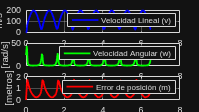

n = min([length(t), length(v), length(w), length(Error)]);
%%%%%%%%%%%%%%%%%%%%%%%%%%%%% Graficas %%%%%%%%%%%%%%%%%%%%%%%%%%%%
graph=figure;  % Crear figura (Escena)
set(graph,'position',sizeScreen); % Congigurar tamaño de la figura
subplot(311)
plot(t(1:n), v(1:n),'b','LineWidth',2),grid('on'),xlabel('Tiempo [s]'),ylabel('m/s'),legend('Velocidad Lineal (v)');
subplot(312)
plot(t(1:n), w(1:n),'g','LineWidth',2),grid('on'),xlabel('Tiempo [s]'),ylabel('[rad/s]'),legend('Velocidad Angular (w)');
subplot(313)
plot(t(1:n), Error(1:n),'r','LineWidth',2),grid('on'),xlabel('Tiempo [s]'),ylabel('[metros]'),legend('Error de posición (m)');

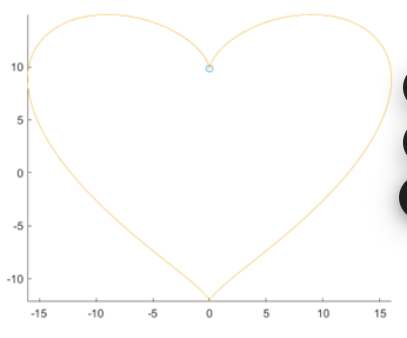

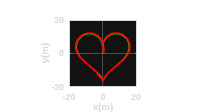

%Limpieza de pantalla
clear all
close all
clc

%1 TIEMPO %%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
%tf=31.5;             % Tiempo de simulación en segundos (s)
tf=6.5;
ts=0.01;            % Tiempo de muestreo en segundos (s)
t=0:ts:tf;         % Vector de tiempo
N= length(t);      % Muestras

%2 CONDICIONES INICIALES %%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%

%Damos valores a nuestro punto inicial de posición y orientación
x1(1)=0;  %Posición inicial eje x
y1(1)=0;  %Posición inicial eje y
phi(1)=0; %Orientación inicial del robot 

%Igualamos el punto de control con las proyecciones X1 y Y1 por su
%coincidencia
hx(1)= x1(1);       % Posición del punto de control en el eje (X) metros (m)
hy(1)= y1(1);       % Posición del punto de control en el eje (Y) metros (m)

%3 TRAYECTORIA DESEADA %%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%

t2   = (t - t(1)) / (t(end) - t(1)) * 2 * pi;   % normalizar a [0, 2π]

hxd  = 16 .* sin(t2).^3;
hyd  = 13.*cos(t2) - 5.*cos(2.*t2) - 2.*cos(3.*t2) - cos(4.*t2);

% Derivadas numéricas
hxdp = gradient(hxd, ts);
hydp = gradient(hyd, ts);


%4 CONTROL, BUCLE DE SIMULACION %%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%

for k=1:N 

    %a)Errores de control (Aqui la posición deseada ya no es constante,
    % varia con el tiempo)
    hxe(k)=hxd(k)-hx(k);
    hye(k)=hyd(k)-hy(k);
    
    %Matriz de error
    he= [hxe(k);hye(k)];
    %Magnitud del error de posición
    Error(k)= sqrt(hxe(k)^2 +hye(k)^2);

    %b)Matriz Jacobiana
    J=[cos(phi(k)) -sin(phi(k));... %Matriz de rotación en 2D
       sin(phi(k)) cos(phi(k))];

    %c)Matriz de Ganancias
    K=[10  0;...
       0  10];
    
    %d)Velocidades deseadas
    hdp=[hxdp(k);hydp(k)];

    %e)Ley de Control:Agregamos las velocidades deseadas
    qpRef= pinv(J)*(hdp + K*he);

    v(k)= qpRef(1);   %Velocidad lineal de entrada al robot 
    w(k)= qpRef(2);   %Velocidad angular de entrada al robot 


%5 APLICACIÓN DE CONTROL AL ROBOT %%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%

    %Aplico la integral a la velocidad angular para obtener el angulo "phi" de la orientación
    phi(k+1)=phi(k)+w(k)*ts; % Integral numérica (método de Euler)
           
   %%%%%%%%%%%%%%%%%%%%% MODELO CINEMATICO %%%%%%%%%%%%%%%%%%%%%%%%%
    
    xp1=v(k)*cos(phi(k)); 
    yp1=v(k)*sin(phi(k));
 
    %Aplico la integral a la velocidad lineal para obtener las cordenadas
    %"x1" y "y1" de la posición
    x1(k+1)=x1(k)+ ts*xp1; % Integral numérica (método de Euler)
    y1(k+1)=y1(k)+ ts*yp1; % Integral numérica (método de Euler)

    % Posicion del robot con respecto al punto de control
    hx(k+1)=x1(k+1); 
    hy(k+1)=y1(k+1);
     

end

%%%%%%%%%%%%%%%%%%%%%%%%%%%%% SIMULACION VIRTUAL 3D %%%%%%%%%%%%%%%%%%%%%%%%%%%%

% a) Configuracion de escena

scene=figure;  % Crear figura (Escena)
set(scene,'Color','white'); % Color del fondo de la escena
set(gca,'FontWeight','bold') ;% Negrilla en los ejes y etiquetas
sizeScreen=get(0,'ScreenSize'); % Retorna el tamaño de la pantalla del computador
set(scene,'position',sizeScreen); % Configurar tamaño de la figura
camlight('headlight'); % Luz para la escena
axis equal; % Establece la relación de aspecto para que las unidades de datos sean las mismas en todas las direcciones.
grid on; % Mostrar líneas de cuadrícula en los ejes
box on; % Mostrar contorno de ejes
xlabel('x(m)'); ylabel('y(m)'); zlabel('z(m)'); % Etiqueta de los eje

view([-0.1 90]); % Orientacion de la figura
axis([-20 20 -20 20 0 1]); % Ingresar limites minimos y maximos en los ejes x y z [minX maxX minY maxY minZ maxZ]

% b) Graficar robots en la posicion inicial
scale = 4;
MobileRobot_5;
H1=MobilePlot_4(x1(1),y1(1),phi(1),scale);hold on;

% c) Graficar Trayectorias
H2=plot3(hx(1),hy(1),0,'r','lineWidth',2);
H3=plot3(hxd,hyd,zeros(1,N),'g','lineWidth',2); %Grafico circulo en posición deseada
%H4=plot3(hx(1),hy(1),0,'go','lineWidth',2);%Grafico circulo en posición inicial
% d) Bucle de simulacion de movimiento del robot

step=1; % pasos para simulacion

for k=1:step:N

    delete(H1);    
    delete(H2);
    
    H1=MobilePlot_4(x1(k),y1(k),phi(k),scale);
    H2=plot3(hx(1:k),hy(1:k),zeros(1,k),'r','lineWidth',2);
    
    pause(ts);

end

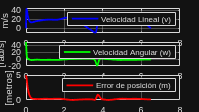

n = min([length(t), length(v), length(w), length(Error)]);
%%%%%%%%%%%%%%%%%%%%%%%%%%%%% Graficas %%%%%%%%%%%%%%%%%%%%%%%%%%%%
graph=figure;  % Crear figura (Escena)
set(graph,'position',sizeScreen); % Congigurar tamaño de la figura
subplot(311)
plot(t(1:n), v(1:n),'b','LineWidth',2),grid('on'),xlabel('Tiempo [s]'),ylabel('m/s'),legend('Velocidad Lineal (v)');
subplot(312)
plot(t(1:n), w(1:n),'g','LineWidth',2),grid('on'),xlabel('Tiempo [s]'),ylabel('[rad/s]'),legend('Velocidad Angular (w)');
subplot(313)
plot(t(1:n), Error(1:n),'r','LineWidth',2),grid('on'),xlabel('Tiempo [s]'),ylabel('[metros]'),legend('Error de posición (m)');